# Linearized Kalman Filter Tuning

This does monte carlo simulations to tune the LKF

% bringing in simulation data and provided data
load sim_setup.mat
load orbitdetermination-finalproj_data_2023_11_14.mat

% Bringing in required functions and variables
addpath('./functions/')

## Simulation Settings and Useful Constants

m = length(a_SRP);                      % number of inputs equals the length of this vector
p = 2;                                  % number of measurement variables per landmark
x_0 = [r_nom; dr_nom];                  % initial state
n = length(x_0);                        % number of state variables
dt = dt_int;                            % chosen step size
t_obs = unique(y_table(:, 1));          % times of observations [s]
t = -dt:dt:max(t_obs);                  % time vector for LKF
steps = length(t);                      % number of time steps in used in LKF
steps_obs = length(t_obs);              % number of observations

% --- number of landmarks to use ---
num_marks = length(pos_lmks_A);
lps = pos_lmks_A(:,1:num_marks);

## ODE Solution with No Noise

This will serve as the nominal states, in which noise gets added to it to create the truth states.

% pure ODE solution with no noise
options = odeset('RelTol',1e-12);               % ODE45 options
[~,x_ode_clean] = ode45(@(t_in,x_in) orbit(t_in,x_in,a_SRP,mu_A), t, x_0', options); % should orbit include inputs?

## System Matrices and Noise

These are static.

% --- Static system matrices ---
% CT B matrix
B = zeros(n,m);
B(4:end,:) = eye(3);

% Static input
u = a_SRP;

% CT Gamma matrix
Gamma = zeros(n,m);
Gamma(4:end,:) = eye(3);

% CT Noise matrices
W_truth = eye(m)*sig_w^2;       % noise matrix for creating truth values
W = eye(m)*sig_w^2;             % noise matrix for KF
V = eye(p)*sig_v^2;
R = V/dt;

% DT noise matrix
Omega = Gamma * dt;
Q_kf = W;

## Monte Carlo Simulation

Varying the pertibations that cause noise to be added to the truth state. 

tic
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% --- Global Monte Carlo Settings -- %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
num_sims = 25;                                  % number of simulations to do
pos_uncert = ones(1,3)*5e-3;                    % position 2-sigma uncertainty on order of meters
vel_uncert = ones(1,3)*5e-6;                    % velocity '                           ' of mm/s
P_0 = diag([pos_uncert.^2/4,vel_uncert.^2/4]);  % Initial uncertainty matrix

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% --- Monte Carlo Loop -- %%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Important things to save each for loop
e_X_all = zeros(n,steps,num_sims);
e_y_all = zeros(p*num_marks,steps_obs,num_sims);
eps_X_all = zeros(steps,num_sims);
eps_y_all = zeros(steps_obs,num_sims);

% running each simulation
for sim = 1:num_sims
    % -- initial uncertainty and pertibations --- %
    x_pert = mvnrnd(zeros(n,1),P_0)';             % Random initial uncertainty gerated from uncertainty matrix

    %%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% --- Truth Model --- %%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%
    % -- State Truth Model --- %
    % adding noise to ODE soln via DT LTI model to get noisy truth states
    dx_DT = zeros(steps,n);
    dx_DT(1,:)= x_pert';
    x_DT = zeros(steps,n);
    x_DT(1,:) = x_0' + x_pert'; % add x_pert here? maybe dont include it?
    for k = 1:steps-1
        % calculating nominal state
        x_nom_k = x_ode_clean(k,:)';

        % Jacobians for nominal state
        A = dfdx(x_nom_k,mu_A);

        % Putting this in the discrete time
        [F,G,Q] = state_CT_to_DT(dt,A,B,Gamma,W_truth);
        w_k = mvnrnd(zeros(n,1),Q)';

        % deviation at the next time step
        dx_k_plus = F*dx_DT(k,:)'+ G*u + w_k; % maybe don't include G*u? more testing with truth model.

        % saving these
        dx_DT(k+1,:) = dx_k_plus';
        x_DT(k+1,:) = x_ode_clean(k+1,:) + dx_k_plus'; % maybe should be x_ode_clean(k,:)?
    end

    % --- Measurement Truth Model --- %
    % Making simulated noisy measurements from these noisy truth states
    x_truth = x_DT;                                 % Choosing truth state model
    % x_truth = x_ode_clean;                        % Choosing truth state model
    y_truth = zeros(p*num_marks,steps_obs);         % 3D array of measurments at each OBSERVATION step.
                                                    %  -->  NOTE: indexing order is strange to not have to flatten results

    % retrieving truth measurments for each measurement step
    for meas_idx = 1:steps_obs
        t_obs_meas = t_obs(meas_idx);               % Time of measurement
        [~,k] = min(abs(t - t_obs_meas));           % index of time for model used
        x_nom_k = x_truth(k,:)';                    % Truth state at this time
                                                    %  CHECK THAT THIS
                                                    %  WORKS FOR FINDING
                                                    %  RIGHT IDX K

        % Making truth observations at observation times
        RNC = R_CtoN(:,:,meas_idx);                 % instrument coordinate system at this time

        % checking measurments for every landmark at this time
        for ii = 1:num_marks
            rows = (p*(ii-1)+1):(p*ii);             % Rows corresponding to this landmark in the measurement matrix
            lp = lps(:,ii);                         % landmark location
            % making the noisy measurement at this time, this satellite
            % location, for this landmark.
            y_truth(rows,meas_idx) = y_measured(lp,x_nom_k,RNC,t(k),true,true); % check that right amount of noise is being added
        end
    end

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %%% --- Linearized Kalman Filter --- %%%
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    % --- Initializing vectors for LKF --- %
    % creating useful vectors for all times
    dx_plus = zeros(steps,n);                               % state correction after measurment
    X_plus = zeros(steps,n);                                % total state after measurement
    P_plus = zeros(n,n,steps);                              % residuals after measurement
    e_X = zeros(n,steps);                                   % state error at each time step
    eps_X = zeros(steps,1);                                 % NEES
    eps_y = zeros(steps_obs,1);                             % NIS

    % initializing these vectors
    dx_plus(1,:) = x_pert';
    X_plus(1,:) =  x_truth(1,:);                            % should pertibation be added here?
    P_plus(:,:,1) = P_0;
    eps_X(1) = dx_plus(1,:)  / (P_plus(:,:,1)) * dx_plus(1,:)';
    e_X(:,1) = dx_plus(1,:);
    % could initialize eps_y, but I'm not going to for now.

    % --- Performing LKF --- %
    % in this for loop, the current time step is k
    % and the next time step is time k+1
    for k = 1:steps-1
        % --- Nominal State calculation ---
        % using the noiseless truth value
        x_nom_k = x_ode_clean(k,:)';
        x_nom_k_plus = x_ode_clean(k+1,:)';
        
        % using the actual truth value
        % x_nom_k = x_truth(k,:)';
        % x_nom_k_plus = x_truth(k+1,:)';

        % --- processes for CURRENT time k ---
        t_k = t(k);                                         % time for this time step
        A = dfdx(x_nom_k,mu_A);                             % Jacobians for nominal state
        [F,G,Q_vanLoan] = state_CT_to_DT(dt,A,B,Gamma,W);   % Putting this in the discrete time

        % Kalman filter prediction step
        dx_minus = F*dx_plus(k,:)' + G*u; % try without forcing input?                   
        
        % Q = Omega * Q_kf * Omega';                        % Choosing to use the KF noise instead of van loan's noise
        Q = Q_vanLoan;                                      % Choosing to use the KF noise instead of van loan's noise
        P_minus = F*P_plus(:,:,k)*F' + Q;

        % If no measurment is available at next time step, make no measurment updates
        t_k_plus = t(k+1);
        if mod(t_k_plus,dt_obs) ~= 0
            dx_plus(k+1,:) = dx_minus';                     % Next state pertibation is uncorrected predicted pertibation
            P_plus(:,:,k+1) = P_minus;                      % residuals for next state is the uncorrected residuals
            X_plus(k+1,:) = x_nom_k_plus' +  dx_minus';     % Next total state is the nominal plus the uncorrected at that state
            % X_plus(k+1,:) = x_nom_k' +  dx_minus';        % Next total state is the nominal plus the uncorrected at that state. nom k? k+1?
            continue                                        % Do not make corrections; skip rest of loop
        end

        % --- processes for NEXT time step k, after measurement taken --- %
        % time, nominal state, and RNC matrix for next time step.
        % Next step? This step?
        meas_idx = t_k_plus / dt_obs + 1;           % is this the right index for observation? are these times lining up?
        RNC = R_CtoN(:, :, meas_idx);                       % ADCS instrument axes at this step

        % Getting valid measurements and landmarks for this time step
        y_meas = y_truth(:,meas_idx);                       % Getting measurements at this time
        vis_rows = find(~isnan(y_meas));                    % finding all the non-NaN rows, corresponding to visible landmarks
        vis_landmarks = vis_rows(2:p:end)/p;                % index of visible landmarks is relatex to the index of non-NaN rows
        num_vis = length(vis_landmarks);                    % number of visible landmarks (Each landmark has p measurements)
        y_meas = y_meas(vis_rows);                          % Filtering for only the visible landmarks

        % initializing nominal measurments, H matrix, and uncertainty matrix
        y_nom = zeros(size(y_meas));                        % initialize nominal measurements
        H = ones(p*num_vis,n);                              % Initialize H matrix
        R_k = kron(eye(num_vis),R);                         % measurement noise matrix. All landmarks have same noise, so diagonal matrix

        % perfoming H matrix calculations and simulated measurements for next time step
        for i = 1:num_vis
            % Getting the visible landmark of interest
            landmark_i = vis_landmarks(i);
            lp = lps(:,landmark_i);                         % landmark coordinates in asteroid-fixed frame

            % getting expected position of landmark at next time step, with no process nosie
            y_nom_i = y_measured(lp, x_nom_k_plus, RNC, t_k_plus,false,false);  % NOMINAL K? NOMINAL K+1? INCLUDE NOISE?

            % obtaining H matrix for this landmark at next time step
            H_i = H_k(lp,x_nom_k_plus,t_k_plus,RNC);                            % NOMINAL K? NOMINAL K+1?

            % storing these values
            rows = (p*(i-1)+1):(p*i);                       % Rows corresponding to this landmark
            y_nom(rows) = y_nom_i;                          % observation difference matrix
            H(rows,:) = H_i;                                % H matrix
        end
        dy_vis = y_meas - y_nom;                            % error in measurement and expected value

        % Kalman filter correction step
        S = H * P_minus * H' + R_k;                         % Innovation matrix
        K = P_minus * H' / (S);                             % Gain matrix
        e_y_k = dy_vis - H*dx_minus;                        % Measurement error
        dx_plus(k+1,:) = (dx_minus + K*e_y_k)';           % correction for next time step
        P_plus(:,:,k+1) = (eye(n) - K*H)*P_minus;           % Uncertainties for next time step
        X_plus(k+1,:) = x_nom_k_plus' + dx_plus(k+1,:);       % Total estimate state for next step. nom k? nom k+1?

        % --- Error calculations --- %
        % state error and NEES
        e_X_k = x_truth(k+1,:)' - X_plus(k+1,:)';
        e_X(:,k+1) = e_X_k;
        eps_X(k+1) = e_X_k' / (P_plus(:,:,k+1)) * e_X_k;

        % measurement error and NIS
        eps_y(meas_idx) = e_y_k' / (S) * e_y_k;
    end

    % saving state errors and NIS/NEES vectors 
    e_X_all(:,:,sim) = e_X;
    eps_X_all(:,sim) = eps_X;
    eps_y_all(:,sim) = eps_y;
end
toc

## Plotting 

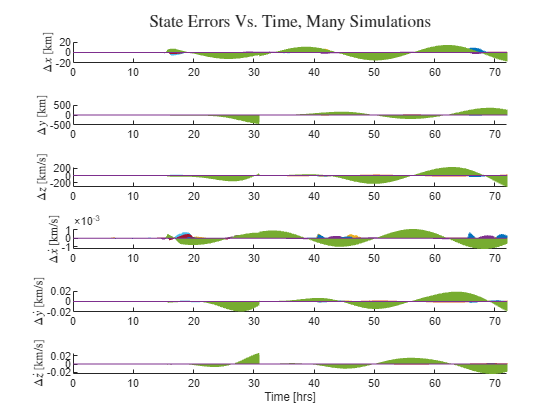

figure(1);
fig = tiledlayout(n,1);
ylabels =   ["$ \Delta x$ [km]", "$ \Delta y$ [km]","$ \Delta z$ [km/s]", ...
    "$ \Delta\dot x$ [km/s]", "$ \Delta\dot y$ [km/s]","$ \Delta\dot z$ [km/s]"];
for i = 1:n
    nexttile(fig)
    hold on
    for sim = 1:num_sims
        plot(t/60/60,e_X_all(i,:,sim))
    end
    hold off
    xlim([t_obs(1)/60/60, 72])
    ylabel(ylabels(i),Interpreter='latex')
end
xlabel("Time [hrs]")
title(fig,"State Errors Vs. Time, Many Simulations", Interpreter='latex')

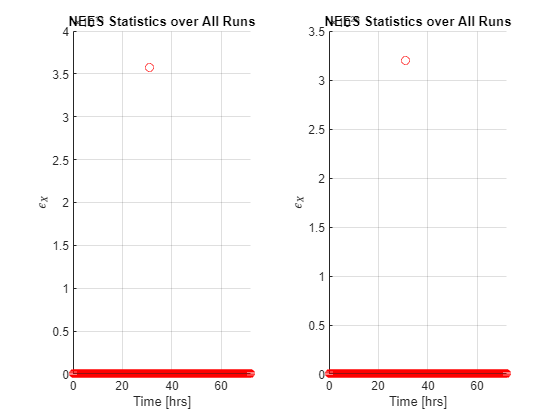


clf
figure(2);
fig = tiledlayout(1,2);

nexttile
% hold on
scatter(t/60/60,(mean(eps_X_all')),'red')
% hold off
grid on 
xlabel("Time [hrs]")
% ylim([0,100])
xlim([0,72])
ylabel("$\epsilon_X$",Interpreter='latex')
title("NEES Statistics over All Runs")

nexttile
% hold on
scatter(t/60/60,(var(eps_X_all')),'red')
% hold off
grid on 
xlabel("Time [hrs]")
% ylim([0,100])
xlim([0,72])
ylabel("$\epsilon_X$",Interpreter='latex')
title("NEES Statistics over All Runs")

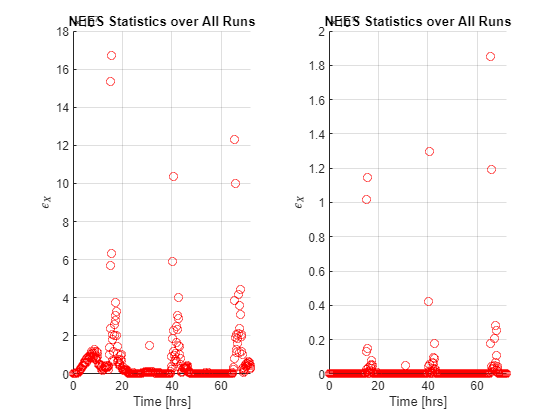


clf
figure(3);
fig = tiledlayout(1,2);

nexttile
% hold on
scatter(t_obs/60/60,(mean(eps_y_all')),'red')
% hold off
grid on 
xlabel("Time [hrs]")
% ylim([0,100])
xlim([0,72])
ylabel("$\epsilon_X$",Interpreter='latex')
title("NEES Statistics over All Runs")

nexttile
% hold on
scatter(t_obs/60/60,(var(eps_y_all')),'red')
% hold off
grid on 
xlabel("Time [hrs]")
% ylim([0,100])
xlim([0,72])
ylabel("$\epsilon_X$",Interpreter='latex')
title("NEES Statistics over All Runs")